clc,clear,close all

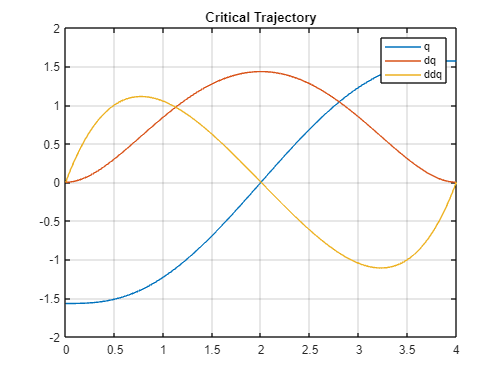

% Dynamical Model of two link Planar Manupulator 

% motor properties
amax=1.05; %[rad/s^2]
mm = [0.3, 0.3];
Im = [54e-6, 54e-6]; %[kg/m^2]
kr = [1/10,1/5];
%kr = [1,1];

%{
% link dimension
lx=[0.20 0.20]; % m
ly=[0.06 0.06]; % m
lz=[0.01 0.01]; % m
%}

% link dimension
lx=[0.170, 0.158]; % m
ly=[0.06 0.06]; % m
lz=[0.007 0.007]; % m



%material properties
density=2660; % [kg/m3] AW 5083 alloy
%rho=(density*1000)/100^3; %[g/cm3]
rho = density; 

mass=[rho*lx(1)*ly(1)*lz(1) rho*lx(2)*ly(2)*lz(2)];

% simulation parameters
methods = dynlib;
Tf = 4;
t_step = 0.01;
[A, ~] = methods.criticaltrajectory(Tf, amax);
t = [0:0.01:Tf];
qd = [];

for i=1:length(t)
    qd=[qd;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end

figure
plot(t, qd);
legend('q', 'dq','ddq');
title('Critical Trajectory');
grid on;


% TODO: Friction?
F = [0.01 0; 0 0.01]; % TEMP

% Initial Values

q0 = [-pi/2;-pi/2];
dq0 = [0;0];
ddq0 = [0;0];

%controller variables
%Kp = diag([ 15 15 ]);
%Kd = diag([ 32 32 ]);

val=[1 1];
Kp=diag((val.^2)./2);
Kd=diag(val);
%wry 

[Bq, Cq, gq, q, dq] = methods.dyn(lx,ly,lz,rho,mm,Im,kr)

$$Bq = \begin{array}{l} \left(\begin{array}{cc} \frac{4270549818223043591\,\cos\left(q_{1}+2\,q_{2}\right)}{900719925474099200000}+\frac{32149163290908063873\,\cos\left(q_{1}+q_{2}\right)}{1125899906842624000000}+\frac{70673062377256442527\,\cos\left(q_{1}\right)}{900719925474099200000}+\frac{12811649454669130773\,\cos\left(q_{2}\right)}{900719925474099200000}+\frac{2932482165750281079110372293445627783}{64903710731685345356631204115251200000} & \sigma_{1}\\ \sigma_{1} & \frac{41323849711628867921\,\cos\left(q_{1}+q_{2}\right)}{2251799813685248000000}+\frac{8892473988578363983\,\cos\left(q_{1}\right)}{225179981368524800000}+\frac{4270549818223043591\,\cos\left(q_{2}\right)}{900719925474099200000}+\frac{716012614279563964064155391183499143}{64903710731685345356631204115251200000} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4270549818223043591\,\cos\left(q_{1}+2\,q_{2}\right)}{1801439850948198400000}+\frac{105622176293444995667\,\cos\left(q_{1}+q_{2}\right)}{4503599627370496000000}+\frac{8892473988578363983\,\cos\left(q_{1}\right)}{225179981368524800000}+\frac{4270549818223043591\,\cos\left(q_{2}\right)}{450359962737049600000}+\frac{715872422264383523686046114204299143}{64903710731685345356631204115251200000} \end{array}$$

$$Cq = \begin{array}{l} \left(\begin{array}{cc} -\frac{{\mathrm{dq}}_{2}\,\left(\frac{4270549818223043591\,\sigma_{1}}{900719925474099200000}+\frac{\sigma_{2}}{90071992547409920000}+\frac{4270549818223043591\,\sin\left(q_{2}\right)}{450359962737049600000}\right)}{2} & -\frac{54057592635734729\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\,\left(79\,\sigma_{1}+170\,\sin\left(q_{1}+q_{2}\right)+158\,\sin\left(q_{2}\right)\right)}{1801439850948198400000}\\ {\mathrm{dq}}_{1}\,\left(\frac{4270549818223043591\,\sigma_{1}}{1801439850948198400000}+\frac{\sigma_{2}}{180143985094819840000}+\frac{4270549818223043591\,\sin\left(q_{2}\right)}{900719925474099200000}\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+2\,q_{2}\right)\\ \sigma_{2}=918979074807490393\,\sin\left(q_{1}+q_{2}\right) \end{array}$$

$$gq = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$

$$dq = \left(\begin{array}{c} {\mathrm{dq}}_{1}\\ {\mathrm{dq}}_{2} \end{array}\right)$$

disp("B(q)=")

B(q)=


vpa(Bq, 5)

$$ans = \begin{array}{l} \left(\begin{array}{cc} 0.0047413\,\cos\left(q_{1}+2.0\,q_{2}\right)+0.028554\,\cos\left(q_{1}+q_{2}\right)+0.078463\,\cos\left(q_{1}\right)+0.014224\,\cos\left(q_{2}\right)+0.045182 & \sigma_{1}\\ \sigma_{1} & 0.018351\,\cos\left(q_{1}+q_{2}\right)+0.039491\,\cos\left(q_{1}\right)+0.0047413\,\cos\left(q_{2}\right)+0.011032 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.0023706\,\cos\left(q_{1}+2.0\,q_{2}\right)+0.023453\,\cos\left(q_{1}+q_{2}\right)+0.039491\,\cos\left(q_{1}\right)+0.0094825\,\cos\left(q_{2}\right)+0.01103 \end{array}$$

disp("C(q, dq)=")

C(q, dq)=


vpa(Cq, 5)

$$ans = \begin{array}{l} \left(\begin{array}{cc} -0.5\,{\mathrm{dq}}_{2}\,\left(0.0047413\,\sigma_{1}+0.010203\,\sin\left(q_{1}+q_{2}\right)+0.0094825\,\sin\left(q_{2}\right)\right) & -0.000030008\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)\,\left(79.0\,\sigma_{1}+170.0\,\sin\left(q_{1}+q_{2}\right)+158.0\,\sin\left(q_{2}\right)\right)\\ {\mathrm{dq}}_{1}\,\left(0.0023706\,\sigma_{1}+0.0051014\,\sin\left(q_{1}+q_{2}\right)+0.0047413\,\sin\left(q_{2}\right)\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+2.0\,q_{2}\right) \end{array}$$